scene_data_train = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-30'

scene_data_train = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-30'

scene_data_test = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-40'

scene_data_test = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-40'

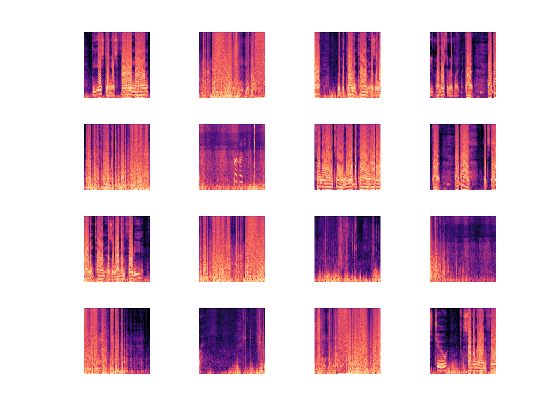


imdsTrain = imageDatastore(scene_data_train, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore(scene_data_test, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end


net = vggish;
